# Electrode Grid and Retina Reference Grid

This file contains five parts:

Part 1 - Parametric electrode grid, drawn to scale (um)

Part 2 - Retina reference grid (degrees of visual angle)

Part 3 - Electrode grid placed on the retina grid

Part 4 - Image to phosphenes (scoreboard model)

Part 5 - Phosphenes placed in the retina frame

The calculations are done by functions defined at the END of this

file (local functions, MATLAB R2016b or later):

create_electrode_grid, place_grid_on_retina, draw_retina_grid,

sample_image_on_grid, render_phosphenes

To use it as a Live Script: Live Editor > Save As > "MATLAB Live Code File (*.mlx)".

clear; clc; close all;

## Electrode grid parameters (declared once)

These parameters are shared by Part 1, Part 3 and Part 4.

Edit them here only.


% --- Electrode grid (lengths in um) ---
nRows    = 16;             % Number of electrodes (rows)
nCols    = 16;             % Number of electrodes (columns)
pitchX   = 250;            % Center-to-center spacing along X [um]
pitchY   = 250;            % Center-to-center spacing along Y [um]
elecDiam = 75;             % Electrode diameter [um]
layout   = "square";       % "square" or "hexagonal"

% --- Electrode dropout model ---
dropoutPercent = 0;       % Percentage of electrodes that are non-functional [0-100]
dropoutSeed    = 42;       % Random seed: keeps the same failed electrodes between runs

% --- Retinal magnification (shared by Part 3 and Part 4) ---
umPerDeg = 288;            % 1 deg = 288 um


## Part 1 - Parametric electrode grid

This part defines the grid parameters and displays the array to scale.

All lengths are expressed in micrometers (um).

%% 1.1 User parameters
% Edit the values below (or replace them with Live Editor controls:
% Insert > Control > Numeric Slider / Drop-Down).

% The electrode grid parameters (nRows, nCols, pitchX, pitchY, elecDiam,
% layout) are declared once at the top of this file.
% "hexagonal" layout shifts every other row by half a pitch.

centerGrid = true;      % true  -> the grid is centered on the origin (0,0)
                        % false -> the first electrode is placed at the origin

%% 1.2 Overlap check
% The function does not know the electrode diameter, so this check is
% done here. Electrodes overlap if the diameter exceeds the smallest pitch.

if elecDiam > min(pitchX, pitchY)
    warning("Electrode diameter (%.0f um) exceeds the smallest pitch " + ...
            "(%.0f um): electrodes will overlap.", ...
            elecDiam, min(pitchX, pitchY));
end

%% 1.3 Create the electrode grid (function call)
% create_electrode_grid validates the inputs and returns:
%   x, y   : column vectors of electrode centers [um], numbered row by row
%   coords : table with columns Index, X_um, Y_um

[x, y, ~] = create_electrode_grid(nRows, nCols, pitchX, pitchY, ...
                                       layout, centerGrid);
nElec = numel(x);   % total number of electrodes

% Generate ONE dropout mask shared by every part of this script.
% dropoutMask(k) = true  -> electrode k is functional
% dropoutMask(k) = false -> electrode k has failed and cannot create a phosphene
assert(dropoutPercent >= 0 && dropoutPercent <= 100, ...
       "dropoutPercent must be between 0 and 100.");

rng(dropoutSeed, 'twister');                 % reproducible random selection
nFailed = round(nElec * dropoutPercent / 100);
failedIdx = randperm(nElec, nFailed);        % random electrode indices
dropoutMask = true(nElec, 1);
dropoutMask(failedIdx) = false;
nFunctional = nnz(dropoutMask);

fprintf('Electrode dropout : %.1f%% (%d/%d electrodes failed; %d functional)\\n', ...
        dropoutPercent, nFailed, nElec, nFunctional);

Electrode dropout : 0.0% (0/256 electrodes failed; 256 functional)\n

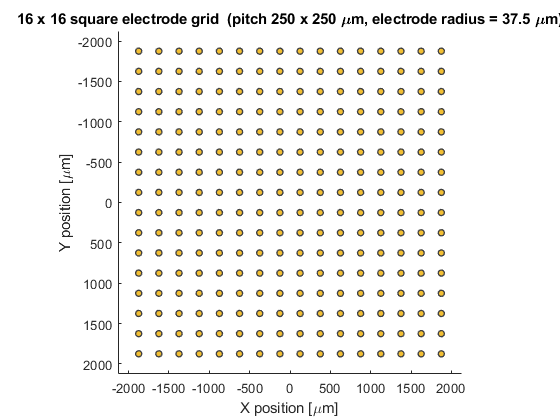


%% 1.4 Display the grid
% Each electrode is drawn as a circle of true diameter (in um), so the
% figure shows the real geometry of the array, including any overlap.

figure('Name', 'Electrode grid', 'Color', 'w');
ax = axes; hold(ax, 'on');

r = elecDiam / 2;   % electrode radius [um]

for k = 1:nElec
    % Functional electrodes are gold; failed electrodes are red.
    if dropoutMask(k)
        faceColor = [0.95 0.75 0.20];
    else
        faceColor = [0.80 0.25 0.25];
    end

    rectangle(ax, ...
        'Position',  [x(k)-r, y(k)-r, elecDiam, elecDiam], ...
        'Curvature', [1 1], ...
        'FaceColor', faceColor, ...
        'EdgeColor', [0.25 0.25 0.25], ...
        'LineWidth', 1);
end

axis(ax, 'equal');   % same scale on X and Y -> circles stay circular
axis(ax, 'ij');      % origin at the upper-left corner, Y axis pointing down
                     % (use axis(ax, 'xy') for the standard Cartesian view)
%grid(ax, 'on');
%box(ax, 'on');

% Add a margin of one pitch around the array so nothing touches the border.
margin = max(pitchX, pitchY);
xlim(ax, [min(x) - margin, max(x) + margin]);
ylim(ax, [min(y) - margin, max(y) + margin]);

xlabel(ax, 'X position [\mum]');
ylabel(ax, 'Y position [\mum]');
title(ax, sprintf('%d x %d %s electrode grid  (pitch %g x %g \\mum, electrode radius = %g \\mum)', ...
      nRows, nCols, layout, pitchX, pitchY, r));

##  Part 2 - Retina reference grid

This part draws a polar reference grid of the retina, expressed in degrees of visual angle and centered on the fovea.

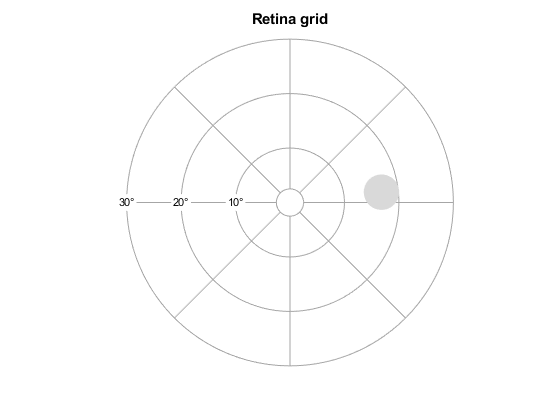

%% 2.1 User parameters
% All values are in degrees of visual angle.

maxEcc      = 30;           % Outermost eccentricity circle [deg]
eccStep     = 10;           % Spacing between concentric circles [deg]
angStep     = 45;           % Angle between radial lines [deg]

odCenter    = [16.8, 1.9];  % Optic disc center [x y] relative to the fovea [deg]
odSize      = [6.5, 6.5];   % Optic disc [width height] [deg]

foveaRadius = 2.5;          % Radius of the fovea marker [deg]

%% 2.2 Draw the retina grid (function call)
% The fovea is at the origin (0, 0). X points right, Y points up.

figure('Name', 'Retina reference grid', 'Color', 'w');
ax = axes;

draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius);

title(ax, sprintf('Retina grid'));

## Part 3 - Electrode grid on the retina

This part builds an electrode grid, rotates it, places it at a given distance from the fovea, and draws it on the retina reference grid.

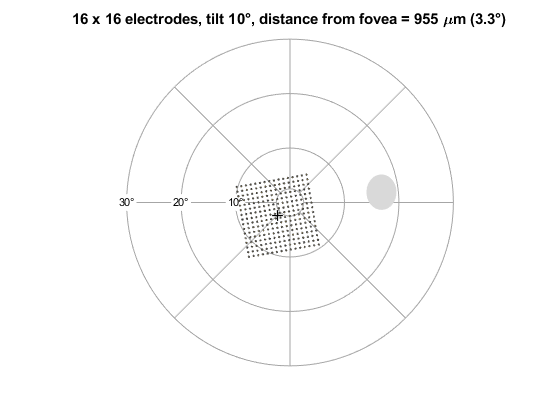

%% 3.1 User parameters

% The electrode grid (nRows, nCols, pitchX, pitchY, elecDiam, layout) and
% umPerDeg are declared once at the top of this file.

% --- Placement on the retina ---
centerOffset = [-650, -700];   % Array center relative to the fovea [x y] [um]
                               % X to the right, Y up
tiltDeg      = 10;              % Array rotation around its center [deg]
                               % positive = counter-clockwise

% --- Retina grid (degrees of visual angle) ---
maxEcc      = 30;           % Outermost eccentricity circle [deg]
eccStep     = 10;           % Spacing between concentric circles [deg]
angStep     = 45;           % Angle between radial lines [deg]
odCenter    = [16.8, 1.9];  % Optic disc center relative to the fovea [deg]
odSize      = [5.5, 6.5];   % Optic disc [width height] [deg]
foveaRadius = 2.5;          % Radius of the fovea marker [deg]

%% 3.2 Create the electrode grid (function call)
% The grid is centered on its own origin so that the rotation and the
% placement are applied around the array center (last argument = true), so
% centerOffset is the position of the array center.

[x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, ...
                                       layout, true);
nElec = numel(x);

%% 3.3 Place the grid on the retina (function call)
% Flip Y, rotate by tiltDeg, translate by centerOffset, convert um -> degrees.

[xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg);

% Useful numbers
centerDeg   = centerOffset / umPerDeg;        % array center [deg]
distanceUm  = norm(centerOffset);             % fovea-to-array distance [um]
distanceDeg = distanceUm / umPerDeg;          % same distance [deg]
elecDiamDeg = elecDiam / umPerDeg;            % electrode diameter [deg]

% Warn if some electrodes fall outside the drawn retina
if any(hypot(xDeg, yDeg) > maxEcc)
    warning("Some electrodes are beyond the outer circle (%g deg).", maxEcc);
end

%% 3.4 Display
% Draw the retina grid first (function call), then each electrode as a
% circle of true size.

figure('Name', 'Electrode grid on the retina', 'Color', 'w');
ax = axes;

draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius);

r = elecDiamDeg / 2;   % electrode radius [deg]
for k = 1:nElec
    % --- CONDITION: Skip drawing if the electrode is outside the retina circle ---
    if hypot(xDeg(k), yDeg(k)) > maxEcc
        continue; 
    end

    % Use exactly the same dropout selection as in Part 1.
    if dropoutMask(k)
        faceColor = [0.95 0.75 0.20];
    else
        faceColor = [0.80 0.25 0.25];
    end

    rectangle(ax, ...
        'Position',  [xDeg(k)-r, yDeg(k)-r, elecDiamDeg, elecDiamDeg], ...
        'Curvature', [1 1], ...
        'FaceColor', faceColor, ...
        'EdgeColor', [0.25 0.25 0.25], ...
        'LineWidth', 0.75);
end

% Mark the array center with a cross
plot(ax, centerDeg(1), centerDeg(2), 'k+', 'MarkerSize', 8, 'LineWidth', 1);

title(ax, sprintf(['%d x %d electrodes, tilt %g%c, distance from fovea = ' ...
      '%.0f \\mum (%.1f%c)'], nRows, nCols, tiltDeg, char(176), ...
      distanceUm, distanceDeg, char(176)));

## Part 4 - Image to phosphenes (scoreboard model)

Takes an image as input and displays the phosphenes that an electrode grid would produce. Pipeline:

   1. electrode grid [um] -> visual angle [deg]  (288 um = 1 deg)

   2. image mapped onto the field of view of the grid

   3. mean intensity at each electrode (box filter = electrode spacing)

   4. quantization to a few gray levels

   5. levels -> stimulation current (0 to 120 uA)

   6. current -> brightness with B = a * C^b

   7. each electrode drawn as a Gaussian phosphene (sigma = sigmaFactor * D)

   8. display: input image and phosphenes (electrodes are NOT drawn)

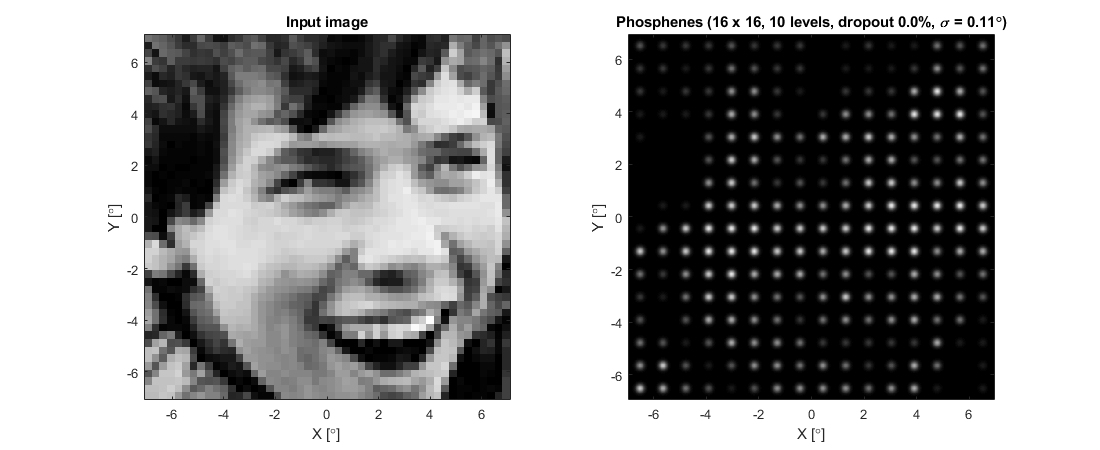

%% 4.1 User parameters

% --- Input image ---
imgFile          = "E:\Documents\Etudes\MVR\Sujet recherche\simulation\SmileTest_1.jpg";     % path to a grayscale or RGB image; '' = synthetic test image
cropToGridAspect = true;   % true -> center-crop the image to the grid's aspect ratio
                           % (avoids deforming the image when it is stretched on the grid)

% The electrode grid (nRows, nCols, pitchX, pitchY, elecDiam, layout) and
% umPerDeg are declared once at the top of this file.

% --- Quantization and stimulation ---
nLevels  = 10;             % Number of gray levels: 2, 4, 8 or 10
Cmax     = 120;            % Current for the brightest level [uA] (range 0 to Cmax)

% --- Brightness model B = a * C^b ---
a = 1.24;
b = 1.02;

% --- Phosphene rendering ---
sigmaFactor    = 0.42;        % sigma = sigmaFactor * D  (D = electrode diameter [deg])

% --- Output image rendering ---
outRes = 60;       % Resolution of the output image [pixel/deg]

assert(nLevels >= 2 && nLevels == round(nLevels), "nLevels must be an integer >= 2.");

%% 4.2 Electrode grid in degrees of visual angle
% create_electrode_grid gives positions in um (grid centered on the origin).
% place_grid_on_retina with no offset and no tilt converts them to degrees
% and puts Y upward. Positions are therefore expressed in the grid's own
% frame (centered on the grid), which is where the image is mapped.

[x, y] = create_electrode_grid(nRows, nCols, pitchX, pitchY, layout, true);
[xDeg, yDeg] = place_grid_on_retina(x, y, [0 0], 0, umPerDeg);

pitchXDeg    = pitchX   / umPerDeg;    % electrode spacing [deg]
pitchYDeg    = pitchY   / umPerDeg;
elecDiamDeg  = elecDiam / umPerDeg;    % electrode diameter [deg]

% Field of view covered by the grid: distance between the outer electrode
% centers plus one pitch, so that each electrode owns a full cell.
widthDeg  = (max(xDeg) - min(xDeg)) + pitchXDeg;
heightDeg = (max(yDeg) - min(yDeg)) + pitchYDeg;

nElec = numel(xDeg);

%% 4.3 Load the input image (grayscale, values in [0, 1])

if ~isempty(imgFile) && isfile(imgFile)
    raw = imread(imgFile);
    if isinteger(raw)
        img = double(raw) / double(intmax(class(raw)));   % uint8 -> [0, 1]
    else
        img = double(raw);
    end
    if size(img, 3) >= 3                                   % RGB -> gray (luminance)
        img = 0.299*img(:,:,1) + 0.587*img(:,:,2) + 0.114*img(:,:,3);
    else
        img = img(:,:,1);
    end
else
    if ~isempty(imgFile)
        warning("File '%s' not found: using the synthetic test image.", imgFile);
    end
    % Synthetic 240 x 240 test image: horizontal ramp + bright disc.
    [X, Y] = meshgrid(linspace(-1, 1, 240));
    img = 0.5 * (X + 1) / 2;
    img(X.^2 + Y.^2 < 0.4^2) = 1;
end

%% 4.4 Map the image onto the grid
% The image is stretched over the field of view of the grid. To keep the
% proportions, the image is first center-cropped to the grid's aspect ratio.

if cropToGridAspect
    [H, W] = size(img);
    target = widthDeg / heightDeg;              % grid aspect ratio (width / height)
    if W / H > target                           % image too wide -> crop columns
        Wn = round(H * target);
        c0 = floor((W - Wn) / 2) + 1;
        img = img(:, c0:c0+Wn-1);
    else                                        % image too tall -> crop rows
        Hn = round(W / target);
        r0 = floor((H - Hn) / 2) + 1;
        img = img(r0:r0+Hn-1, :);
    end
end

%% 4.5 Mean intensity at each electrode (function call)
% Electrode -> nearest pixel; intensity = box-filter mean whose size is the
% electrode spacing converted to pixels (rounded to an odd number).

[I, ~, ~, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, ...
                                    pitchXDeg, pitchYDeg, widthDeg, heightDeg);

%% 4.6 Quantization
% Map the mean intensity [0, 1] to nLevels equally spaced values in [0, 1].

Iq = round(I * (nLevels - 1)) / (nLevels - 1);

%% 4.7 Stimulation current and brightness
% Quantized level -> current between 0 and Cmax, then B = a * C^b.
% B is normalized by its value at Cmax so that the brightest level is 1
% (white); level 0 gives C = 0, hence no phosphene.

C    = Iq * Cmax;               % current of each electrode [uA]
B    = a * C.^b;                % brightness (rating units)
Bmax = a * Cmax^b;              % brightness at the maximum current
Bn   = B / Bmax;                % normalized brightness in [0, 1]

% Electrode failure overrides the image-derived brightness.
% A failed electrode produces no phosphene, even if its pixel is white.
Bn(~dropoutMask) = 0;

%% 4.8 Render the phosphenes (function call)
% Gaussian phosphenes, sigma = sigmaFactor * D.

sigmaDeg = sigmaFactor * elecDiamDeg;
[P, xg, yg] = render_phosphenes(xDeg, yDeg, Bn, sigmaDeg, widthDeg, heightDeg, outRes);

%% 4.9 Display: input image (left) and phosphenes (right)
% Electrodes are not drawn, only the resulting phosphenes.

figure('Name', 'Phosphene simulation', 'Color', 'w', 'Position', [100 100 1100 450]);

ax1 = subplot(1, 2, 1);
imagesc(ax1, [-widthDeg/2 widthDeg/2], [heightDeg/2 -heightDeg/2], img);
set(ax1, 'YDir', 'normal', 'CLim', [0 1]);   % Y up, image upright
colormap(ax1, 'gray'); axis(ax1, 'image');
xlabel(ax1, 'X [\circ]'); ylabel(ax1, 'Y [\circ]');
title(ax1, 'Input image');

ax2 = subplot(1, 2, 2);
imagesc(ax2, [xg(1) xg(end)], [yg(1) yg(end)], P);
set(ax2, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax2, 'gray'); axis(ax2, 'image');
xlabel(ax2, 'X [\circ]'); ylabel(ax2, 'Y [\circ]');
title(ax2, sprintf('Phosphenes (%d x %d, %d levels, dropout %.1f%%, \\sigma = %.2f\\circ)', ...
      nRows, nCols, nLevels, dropoutPercent, sigmaDeg));

%% 4.10 Summary

fprintf('Field of view      : %.2f x %.2f deg\n', widthDeg, heightDeg);

Field of view      : 13.89 x 13.89 deg


fprintf('Image resolution   : %.1f (X) x %.1f (Y) pixel/deg\n', pxPerDeg(1), pxPerDeg(2));

Image resolution   : 3.5 (X) x 3.5 (Y) pixel/deg


fprintf('Box filter size    : %d x %d pixels (odd)\n', filtSize(1), filtSize(2));

Box filter size    : 3 x 3 pixels (odd)


fprintf('Gaussian sigma     : %.3f deg (D = %.3f deg)\n', sigmaDeg, elecDiamDeg);

Gaussian sigma     : 0.109 deg (D = 0.260 deg)


fprintf('Brightness at Cmax : B = %.1f (used to normalize to 1)\n', Bmax);

Brightness at Cmax : B = 163.8 (used to normalize to 1)



isFunctional = dropoutMask;
results = table((1:nElec)', xDeg, yDeg, isFunctional, I, Iq, C, Bn, ...
    'VariableNames', {'Index', 'X_deg', 'Y_deg', 'Functional', 'MeanIntensity', ...
                      'Quantized', 'Current_uA', 'Brightness'});
disp(head(results, 20));

    Index     X_deg      Y_deg     Functional    MeanIntensity    Quantized    Current_uA    Brightness
    _____    ________    ______    __________    _____________    _________    __________    __________

      1       -6.5104    6.5104      true           0.32549        0.33333           40       0.32609  
      2       -5.6424    6.5104      true           0.26449        0.22222       26.667       0.21564  
      3       -4.7743    6.5104      true           0.25403        0.22222       26.667       0.21564  
      4       -3.9063    6.5104      true           0.23355        0.22222       26.667       0.21564  
      5       -3.0382    6.5104      true           0.34074        0.33333           40       0.32609  

### Part 5 - Phosphenes in the retina frame

The phosphenes computed in Part 4 are placed at the retinal position oftheir electrode,

i.e. the position of the grid on the retina set in Part 3 (centerOffset and tiltDeg). Everything that is not a phosphene is black, and the retina reference grid is NOT drawn.

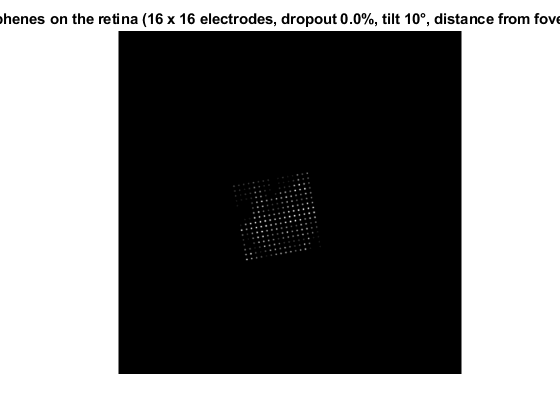

%% 5.1 Parameters
showAxes       = false;    % true -> show the X/Y axes in degrees (still no retina grid)

% The displayed field of view is the square [-maxEcc, maxEcc] x [-maxEcc, maxEcc]
% centered on the fovea (maxEcc, centerOffset and tiltDeg come from Part 3).

%% 5.2 Electrode positions on the retina & Retinal Masking
% Part 4 expressed the electrodes in the grid's own frame (centered, no tilt).
% Here the SAME electrodes (same order, so same brightness Bn) are placed with
% the offset and the tilt of Part 3. x and y [um] come from Part 4.

[xRet, yRet] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg);

% --- Mask to exclude electrodes outside the retina reference circle (maxEcc) ---
insideRetinaMask = hypot(xRet, yRet) <= maxEcc;

% Apply mask: zero out brightness for electrodes outside the retina boundary
Bn_retina = Bn; 
Bn_retina(~insideRetinaMask) = 0;

% Warn if some phosphenes fall outside the displayed field of view
nOutside = nnz(~insideRetinaMask);
if nOutside > 0
    warning("%d electrodes are outside the retina circle (%g deg) and their phosphenes have been masked.", ...
        nOutside, maxEcc);
end

%% 5.3 Render the phosphenes on the retina (function call)
% Same Gaussian phosphenes as in Part 4 (same sigma and brightness), on a
% black canvas covering the retina. Outside electrodes have 0 brightness and won't render.

[Pret, xr, yr] = render_phosphenes(xRet, yRet, Bn_retina, sigmaDeg, ...
                                   2*maxEcc, 2*maxEcc, outRes);

%% 5.4 Display
% Only the phosphenes are shown (electrodes and retina grid are not drawn).

figure('Name', 'Phosphenes on the retina', 'Color', 'w');
ax = axes;

imagesc(ax, [xr(1) xr(end)], [yr(1) yr(end)], Pret);
set(ax, 'YDir', 'normal', 'CLim', [0 1]);   % Y up, same convention as the retina grid
colormap(ax, 'gray'); axis(ax, 'image');

if showAxes
    xlabel(ax, 'X [\circ]'); ylabel(ax, 'Y [\circ]');
else
    axis(ax, 'off');
end

title(ax, sprintf(['Phosphenes on the retina (%d x %d electrodes, dropout %.1f%%, tilt %g%c, ' ...
      'distance from fovea = %.1f%c)'], nRows, nCols, dropoutPercent, tiltDeg, char(176), ...
      distanceDeg, char(176)));

 ======================================================================

##                                        FUNCTIONS

                  (they must stay at the end of the file, after all the script code)

 ======================================================================

### *create_electrode_grid*  Compute the center positions of an electrode array.

   [x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, layout, centerGrid)

   Inputs

     nRows      - number of electrodes along the vertical axis (rows)

     nCols      - number of electrodes along the horizontal axis (columns)

     pitchX     - center-to-center spacing along X [um]

     pitchY     - center-to-center spacing along Y [um]

     layout     - "square" or "hexagonal" (odd rows shifted by pitchX/2)

     centerGrid - true  -> grid centered on the origin (0,0)

                  false -> first electrode placed at the origin

   Outputs

     x, y       - column vectors (nElec x 1) of electrode centers [um],

                  numbered row by row (left to right, top to bottom)

     coords     - table with columns Index, X_um, Y_um

   Coordinate convention: Y grows with the row index (image convention,

   Y pointing DOWN). When plotting, call axis(ax, 'ij') so that electrode

   #1 appears at the top-left.

function [x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, layout, centerGrid)
    % ---- Input validation: fail early with a clear message ----
    assert(nRows >= 1 && nCols >= 1 && ...
           nRows == round(nRows) && nCols == round(nCols), ...
           "nRows and nCols must be positive integers.");
    assert(pitchX > 0 && pitchY > 0, "Pitches must be strictly positive.");
    assert(ismember(layout, ["square", "hexagonal"]), ...
           "layout must be ""square"" or ""hexagonal"".");

    % ---- Grid indices ----
    % meshgrid builds one (column, row) index pair for every electrode.
    % Indices start at 0, so the first electrode sits at the origin.
    [colIdx, rowIdx] = meshgrid(0:nCols-1, 0:nRows-1);

    % ---- Scale indices into physical positions [um] ----
    x = colIdx * pitchX;
    y = rowIdx * pitchY;

    % ---- Hexagonal layout: shift odd rows by half a pitch along X ----
    if layout == "hexagonal"
        oddRows = mod(rowIdx, 2) == 1;       % logical mask of odd rows
        x(oddRows) = x(oddRows) + pitchX/2;  % half-pitch offset
    end

    % ---- Flatten into column vectors, one entry per electrode ----
    % MATLAB's (:) reads a matrix column by column, so we transpose first
    % (.') to obtain a row-by-row numbering (left to right, top to bottom).
    x = x.';  x = x(:);
    y = y.';  y = y(:);

    % ---- Optionally recenter the whole array on the origin ----
    if centerGrid
        x = x - (max(x) + min(x)) / 2;
        y = y - (max(y) + min(y)) / 2;
    end

    % ---- Table of all electrode positions ----
    nElec  = numel(x);
    coords = table((1:nElec)', x, y, ...
                   'VariableNames', {'Index', 'X_um', 'Y_um'});
end

### *place_grid_on_retina*  Rotate and translate an electrode grid onto the retina grid.

   [xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg)

   Inputs

     x, y         - electrode centers [um] from create_electrode_grid,

                    centered on the array center (centerGrid = true)

     centerOffset - [x y] position of the array center relative to the

                    fovea [um]; X to the right, Y up

     tiltDeg      - rotation of the array around its own center [deg],

                    positive = counter-clockwise

     umPerDeg     - retinal magnification: micrometers per degree of

                    visual angle (288 um/deg)

   Outputs

     xDeg, yDeg   - electrode centers in the retina grid frame [deg],

                    fovea at the origin, Y pointing up

   Steps: (1) flip Y, (2) rotate, (3) translate, (4) convert um -> deg.

function [xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg)
    % ---- 1. Match the retina convention (Y up) ----
    % create_electrode_grid uses the image convention (Y down, electrode #1
    % at the top-left). Negating y keeps electrode #1 at the top-left on
    % the retina grid, whose Y axis points up.
    y = -y;

    % ---- 2. Rotate around the array center (the local origin) ----
    % Standard 2-D rotation matrix applied to every electrode.
    xRot = x * cosd(tiltDeg) - y * sind(tiltDeg);
    yRot = x * sind(tiltDeg) + y * cosd(tiltDeg);

    % ---- 3. Translate: move the array center to its position vs. the fovea ----
    xRot = xRot + centerOffset(1);
    yRot = yRot + centerOffset(2);

    % ---- 4. Convert micrometers to degrees of visual angle ----
    xDeg = xRot / umPerDeg;
    yDeg = yRot / umPerDeg;
end

### *draw_retina_grid*  Draw a polar reference grid of the retina (no axon fibers).

   draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius)

   The grid is expressed in degrees of visual angle and is centered on the fovea, which sits at the origin (0, 0).

   Inputs

     ax          - axes handle to draw into

     maxEcc      - outermost eccentricity circle [deg]

     eccStep     - spacing between concentric circles [deg]

     angStep     - angle between radial lines [deg]

     odCenter    - optic disc center [x y] in degrees

     odSize      - optic disc [width height] in degrees

     foveaRadius - radius of the fovea marker [deg]

   Convention: X points to the right, Y points up (standard Cartesian view).

function draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius)
    % ---- Input validation: fail early with a clear message ----
    assert(maxEcc > 0 && eccStep > 0 && eccStep <= maxEcc, ...
           "Eccentricities must satisfy 0 < eccStep <= maxEcc.");
    assert(angStep > 0 && angStep <= 180, "angStep must be in ]0, 180].");

    hold(ax, 'on');
    gridColor = [0.65 0.65 0.65];   % light gray for all grid lines
    t = linspace(0, 2*pi, 361);     % angles used to draw circles / ellipses

    % ---- Concentric circles (constant eccentricity) ----
    eccList = eccStep:eccStep:maxEcc;   % e.g. 10, 20, 30 deg
    for e = eccList
        % x = e*cos(t) and y = e*sin(t) describe a circle of radius e
        plot(ax, e*cos(t), e*sin(t), 'Color', gridColor, 'LineWidth', 0.75);
    end

    % ---- Radial lines (constant polar angle) ----
    % Each line goes from the fovea (origin) to the outermost circle.
    % With angStep = 45, the horizontal and vertical axes are included.
    for a = 0:angStep:(360 - angStep)
        plot(ax, [0, maxEcc*cosd(a)], [0, maxEcc*sind(a)], ...
             'Color', gridColor, 'LineWidth', 0.75);
    end

    % ---- Eccentricity labels along the left half of the horizontal axis ----
    % The white background hides the grid line behind the text.
    for e = eccList
        text(ax, -e, 0, sprintf('%g%c', e, char(176)), ...
             'HorizontalAlignment', 'center', ...
             'VerticalAlignment',   'middle', ...
             'BackgroundColor',     'w', ...
             'Margin',              1, ...
             'FontSize',            8);
    end

    % ---- Optic disc: filled gray ellipse ----
    % Ellipse centered on odCenter, with semi-axes = size / 2.
    odX = odCenter(1) + (odSize(1)/2) * cos(t);
    odY = odCenter(2) + (odSize(2)/2) * sin(t);
    fill(ax, odX, odY, [0.85 0.85 0.85], 'EdgeColor', 'none');

    % ---- Fovea: white disc at the origin, drawn last so it hides the lines ----
    fill(ax, foveaRadius*cos(t), foveaRadius*sin(t), 'w', ...
         'EdgeColor', gridColor, 'LineWidth', 0.75);

    % ---- Axes appearance ----
    axis(ax, 'equal');                                  % same scale on X and Y -> true circles
    axis(ax, [-maxEcc maxEcc -maxEcc maxEcc] * 1.05);   % small margin around the grid
    axis(ax, 'off');                                    % no ticks, the grid itself is the reference
end

### sample_image_on_grid  Mean image intensity at each electrode (box filter).

   [I, rowE, colE, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, ...

                              pitchXDeg, pitchYDeg, widthDeg, heightDeg)

   The image is stretched over the field of view covered by the grid (widthDeg x heightDeg).

    Each electrode is placed on the nearest pixel, and its intensity is the mean of the image over a box of size "electrode spacing", read at that pixel.

   Inputs

     img        - grayscale image (H x W), double, values in [0, 1]

     xDeg,yDeg  - electrode centers [deg], origin = grid center, Y UP

     pitchXDeg  - horizontal electrode spacing [deg]

     pitchYDeg  - vertical electrode spacing [deg]

     widthDeg   - width  of the field of view covered by the image [deg]

     heightDeg  - height of the field of view covered by the image [deg]

   Outputs

     I          - mean intensity at each electrode (nElec x 1), in [0, 1]

     rowE,colE  - pixel row / column of each electrode

     pxPerDeg   - [horizontal vertical] image resolution [pixel/deg]

     filtSize   - [height width] of the box filter [pixels] (odd numbers)


function [I, rowE, colE, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, pitchXDeg, pitchYDeg, widthDeg, heightDeg)
    [H, W] = size(img);

    % ---- 1. Image resolution in pixels per degree ----
    % Image size in pixels divided by the field of view in degrees.
    pxPerDegX = W / widthDeg;
    pxPerDegY = H / heightDeg;
    pxPerDeg  = [pxPerDegX, pxPerDegY];

    % ---- 2. Electrode position in pixels (rounded to the nearest pixel) ----
    % The image center is the grid center. Rows grow downward, Y grows upward.
    cx   = (W + 1) / 2;
    cy   = (H + 1) / 2;
    colE = round(cx + xDeg(:) * pxPerDegX);
    rowE = round(cy - yDeg(:) * pxPerDegY);
    colE = min(max(colE, 1), W);     % safety: stay inside the image
    rowE = min(max(rowE, 1), H);

    % ---- 3. Box filter size = electrode spacing converted to pixels ----
    % Rounded to the NEAREST ODD integer so the window is centered on a pixel.
    toOdd = @(n) max(1, 2 * round((n - 1) / 2) + 1);
    nw = toOdd(pitchXDeg * pxPerDegX);   % filter width  [px]
    nh = toOdd(pitchYDeg * pxPerDegY);   % filter height [px]
    filtSize = [nh, nw];

    % ---- 4. Mean filter (box kernel convolved with the image) ----
    % K sums to 1, so each output pixel is the mean of the nh x nw pixels
    % around it. Outside the image the pixels count as 0.
    K = ones(nh, nw) / (nh * nw);
    filtered = conv2(img, K, 'same');          % or: filtered = iconvolve(K, img);

    % ---- 5. Read the filtered image at each electrode pixel ----
    I = filtered(sub2ind([H, W], rowE, colE));
end

### *render_phosphenes*  Draw one Gaussian phosphene per electrode on a black background.

   [P, xg, yg] = render_phosphenes(xDeg, yDeg, amp, sigmaDeg, widthDeg, heightDeg, outRes)

   Each phosphene is a 2-D Gaussian centered on its electrode, whose peak value is the brightness of that electrode

   Overlapping phosphenes add up, and the result is clipped to 1.

   Inputs

     xDeg,yDeg  - electrode centers [deg], origin = grid center, Y UP

     amp        - brightness of each electrode (nElec x 1), in [0, 1]

     sigmaDeg   - standard deviation of the Gaussian [deg]

     widthDeg   - width  of the displayed field of view [deg]

     heightDeg  - height of the displayed field of view [deg]

     outRes   - resolution of the output image [pixel/deg]

   Outputs

     P          - phosphene image (Ny x Nx), values in [0, 1]; row 1 is the TOP

     xg, yg     - coordinate vectors of the columns / rows [deg]

function [P, xg, yg] = render_phosphenes(xDeg, yDeg, amp, rho, widthDeg, heightDeg, outRes)

    Nx = round(widthDeg  * outRes);
    Ny = round(heightDeg * outRes);

    xg = linspace(-widthDeg/2,  widthDeg/2,  Nx);   % 1 x Nx, left to right
    yg = linspace( heightDeg/2, -heightDeg/2, Ny);  % 1 x Ny, top to bottom

    % A 2-D Gaussian is separable: exp(-(dx^2+dy^2)/(2s^2)) = gx(dx) * gy(dy).
    % So the sum over all electrodes is a single matrix product (no loop).
    Gx = exp(-(xg - xDeg(:)).^2 / (2 * rho^2));   % nElec x Nx
    Gy = exp(-(yg - yDeg(:)).^2 / (2 * rho^2));   % nElec x Ny

    P = Gy' * (amp(:) .* Gx);   % (Ny x nElec) * (nElec x Nx) = Ny x Nx
    P = min(P, 1);              % clip where phosphenes overlap
end

